## Buck simulation

From an uncharged system:

L=100e-3; %Coil
C=1000e-6; %Capacitor
R=10; %Ohm Resistance Output
Ve=200;
A=[0 -1/L; 1/C -1/R/C];
B=[1/L; 0]*Ve;
T=0.005;

Continuous representation:

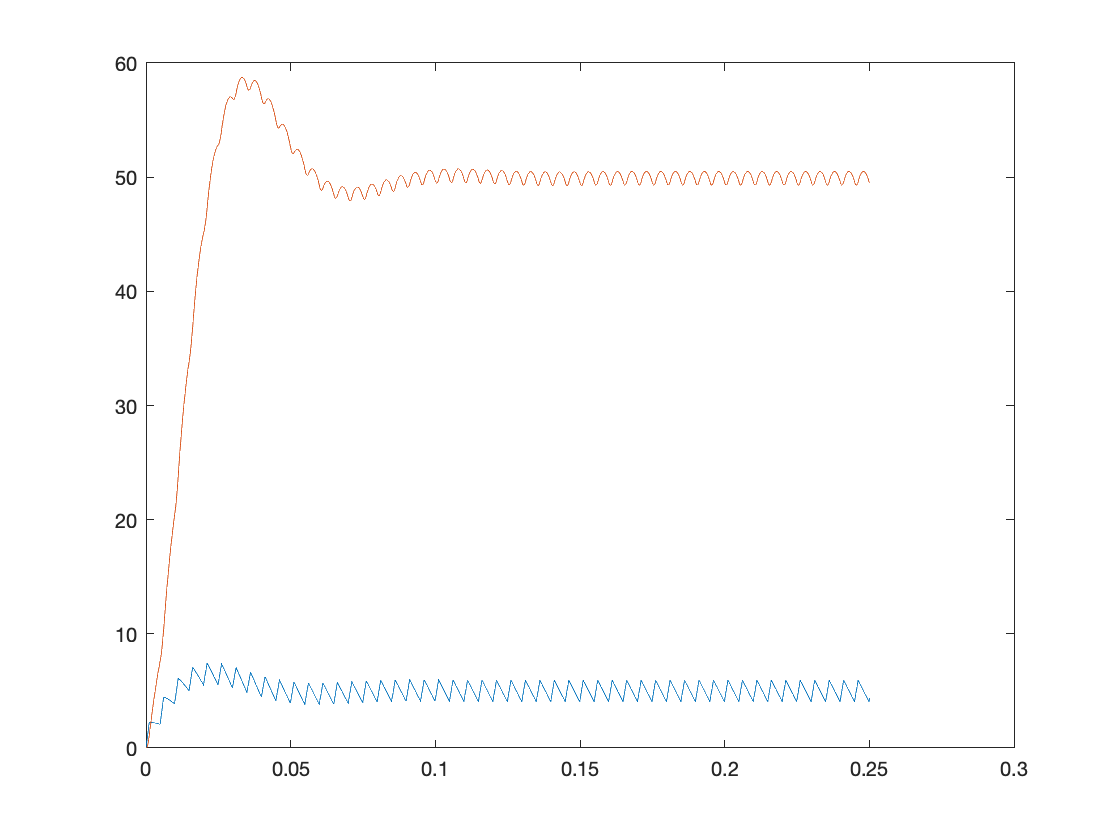

Td=T/40;
N=50*40;
delta=0.25;
x=zeros(2,N);
x(:,1)=[0;0];
for i=1:N+1
    if (mod(i,40)/40<0.25)
       x(:,i+1)=x(:,i)+Td*(A*x(:,i)+B);
    else
       x(:,i+1)=x(:,i)+ Td*A*x(:,i);
    end
    if (x(1,i+1)<0)
        x(1,i+1)=0;
    end
end
figure
t=[0 (1:N+1)*Td];
plot(t,x')  

Discrete representation:

Ad=expm(A*T);
Bd=expm(A*T)*(eye(2)-expm(-A*T*delta))*inv(A)*B;
N=50;
delta=0.25;
x2=zeros(2,N);
x2(:,1)=[0;0];
for i=1:N+1
    x2(:,i+1)=Ad*x2(:,i)+Bd;
end
%figure
t2=[0 (1:N+1)*T];
%plot(t2,x2','x')  

Overlapped:

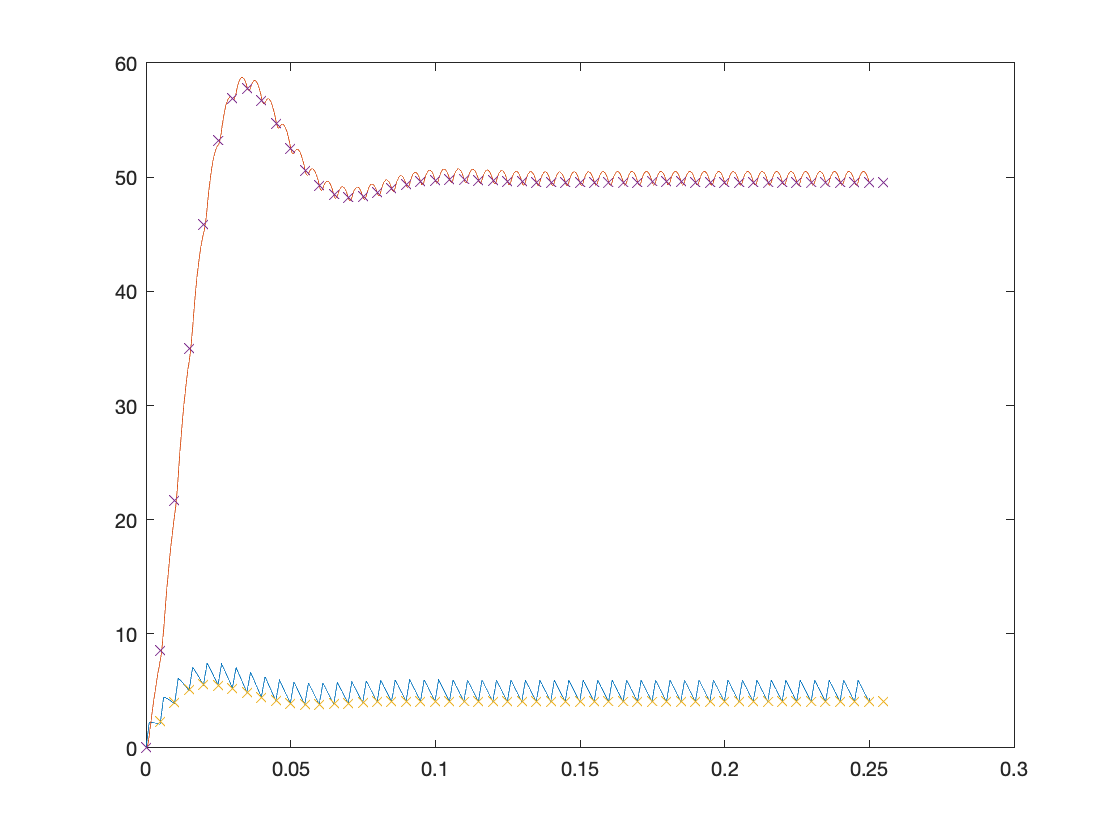

figure
plot(t,x')  
hold on
plot(t2,x2,'x')

Fuzzy discrete system representation:

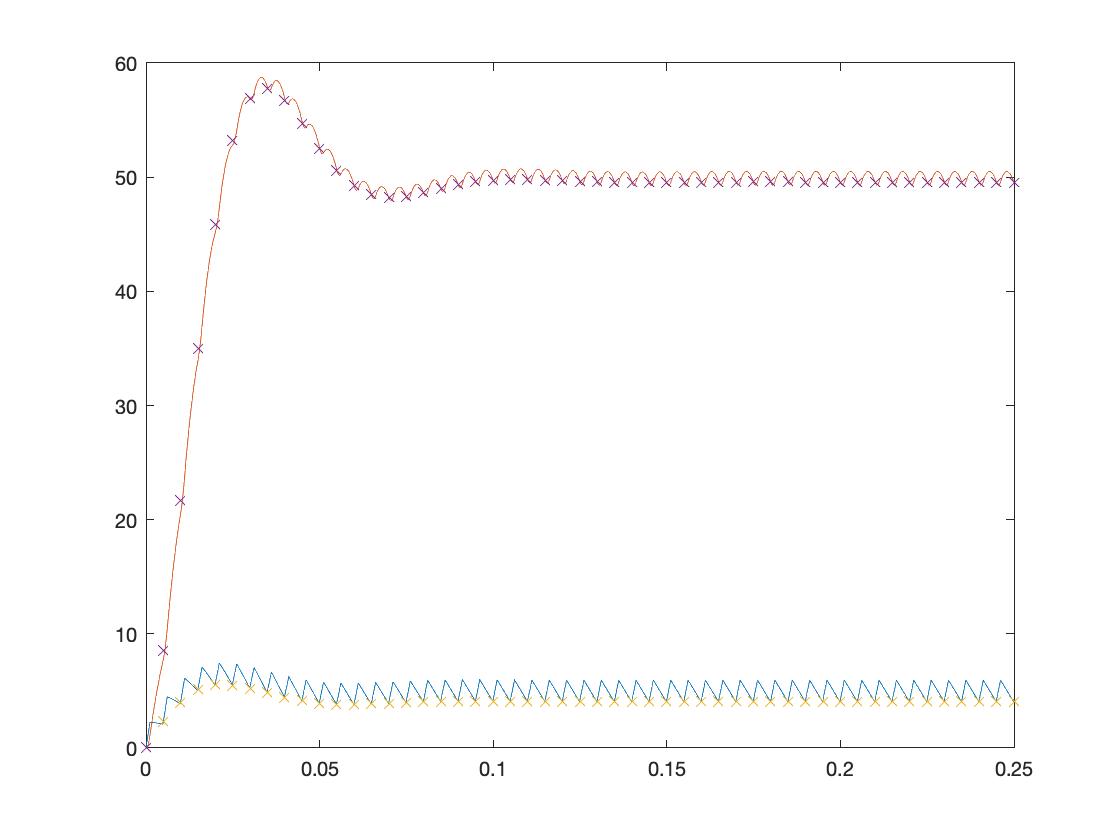

L=100e-3; %Coil
C=1000e-6; %Capacitor
R=10; %Ohm Resistance Output
Ve=200;
A=[0 -1/L; 1/C -1/R/C];
B=[1/L; 0]*Ve;
T=0.005;
[PA,PB,alpha2]=discrete_binary_f(A,B,T); %Fuzzy binary discretization function

%%%%%%%
delta=[0.25]; % Delta 1, the control action triggers the full duty cycle, 
%in this case, only triggers one fourth
N=50*20; %Number of cycles
x2=zeros(length(A),N);
x2(:,1)=[0,0]'; %Initial state
alpha=[];
r=rank(A);
for j=1:length(alpha2)
    i=ceil(j/r);
    alpha=[alpha (1-alpha2{j}(delta(i))) alpha2{j}(delta(i))];
end
%Calculates each X value for each period of time.
for i=1:N+1
    x2(:,i+1)=PA*x2(:,i)+PB.eval(alpha)*delta';
end
t2=[0 (1:N+1)*T];
figure
plot(t,x') 
hold on
plot(t2,x2','x')
hold off
ylim([0 60])
xlim([0 0.25])

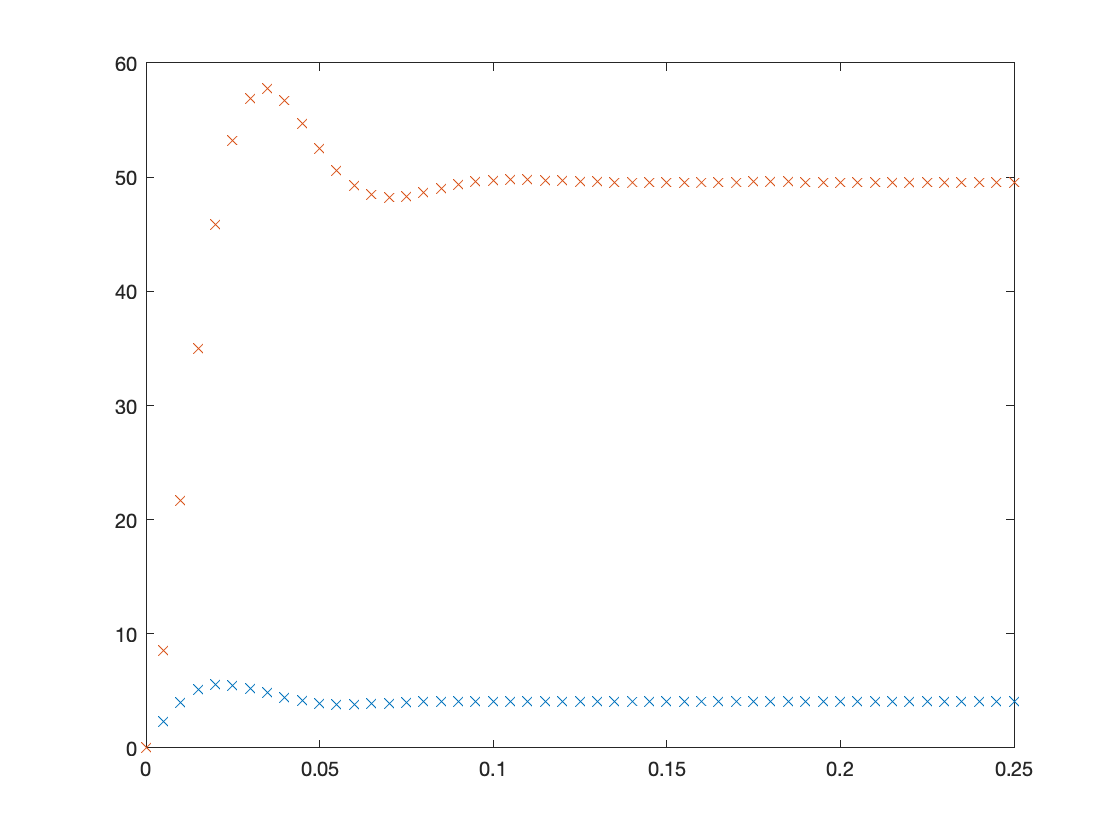

figure
plot(t2,x2','x')
ylim([0 60])
xlim([0 0.25])

# MATCHES!! 